# Visualization of graph data

## Small graph data

addpath("functions")
addpath("..\tristan_graph_data")
load materials\building.mat
set(0,'DefaultFigureWindowStyle','docked')

The sparsity patterns for the Sin and Cos matrices.

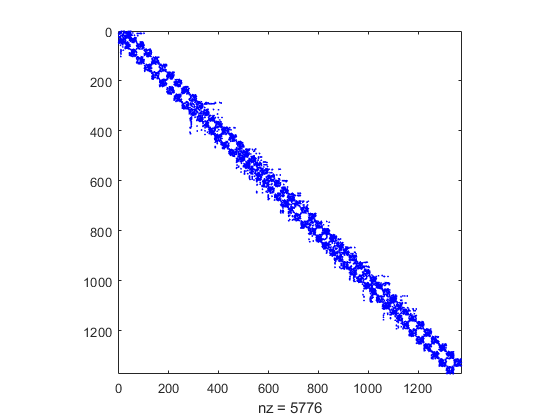

spy(Cos,'.b');

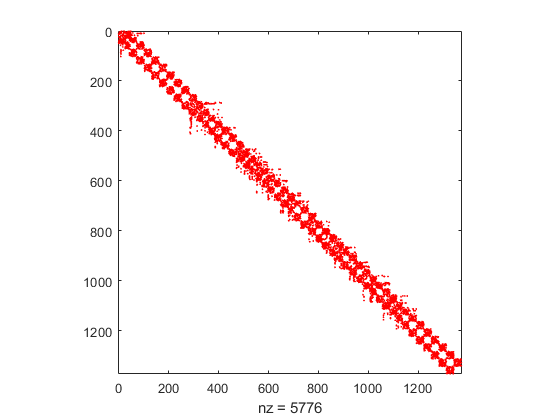

spy(Sin,'r');

The pattern of Cos and Sin having values at different indices.

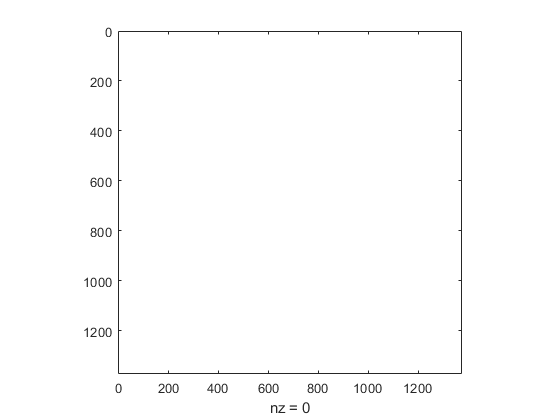

spy(double(Cos~=0) - double(Sin~=0));

The head of the M matrix. Its pattern should be falling diagonals with verticals at each iteration.

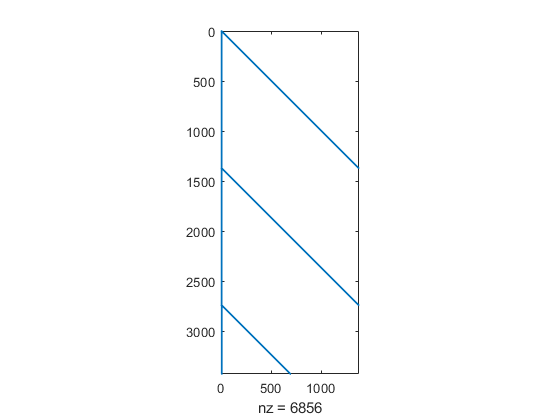

spy(headN(M,ceil(2.5*n)));

Plot here the actual graph that is given. **Cos** does function as the adjacency matrix here. For the real adjacency matrix get the nonzeros from Cos. If no adjacency is given we can take only the vertices without interconnections. *(See section ****large graph****)*

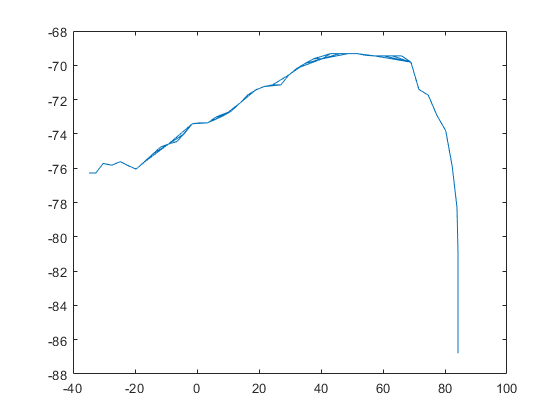

gplot(Cos,nodes(:,2:3))

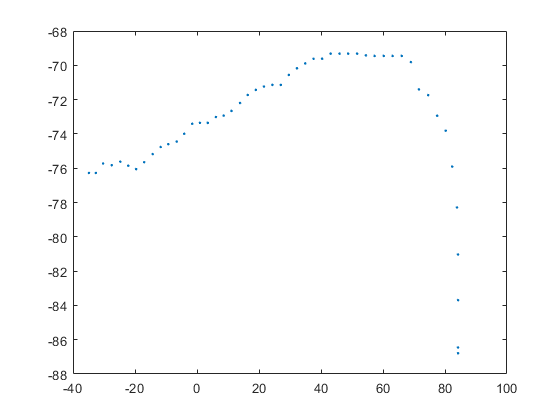

plot(nodes(:,2),nodes(:,3),".")

Display the first embedding solution. This embedding was calculated by improper usage of **inv()**.

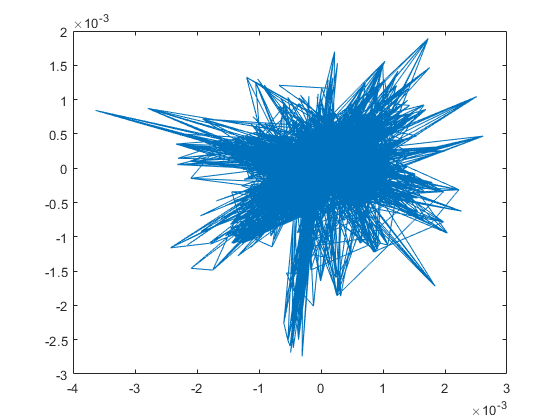

gplot(Cos,emb1)

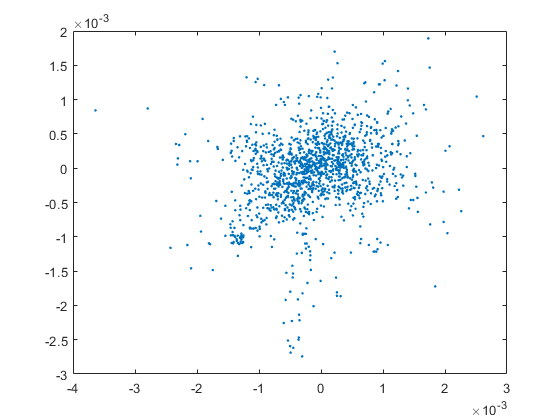

plot(emb1(:,1),emb1(:,2),".")

Display the second embedding solution. This embedding was calculated by the proper way of **A\b**. Here **b** was a matrix as well. *(See ****building.mlx****)*

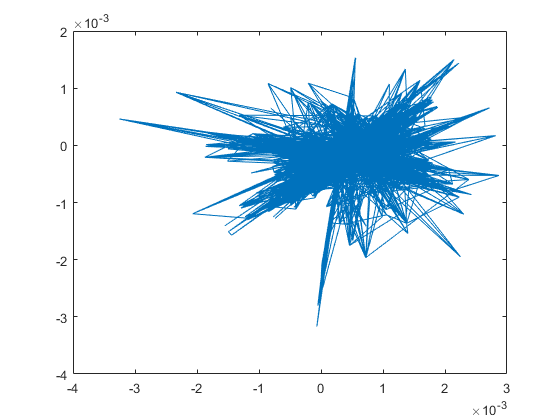

gplot(Cos,emb2)

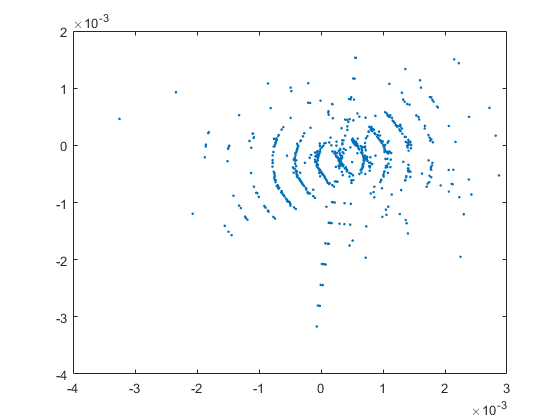

plot(emb2(:,1),emb2(:,2),".")

On this last graph there is visible some circular structure. This is interesting in a way that it differs the first version of the improper usage of **inv()** a lot. This might be interesting for understanding the desired solution of embeddings and worth discussing more.

## Large graph data

Here we want to use the **large data set** Tristan gave us instead of the partial one above. Due to the large number of nodes and edges we cannot calculate an adjacency matrix. This would break the limit of data storage as it demands **9.4GB**. As for now we just display the nodes without interconnecting edges.

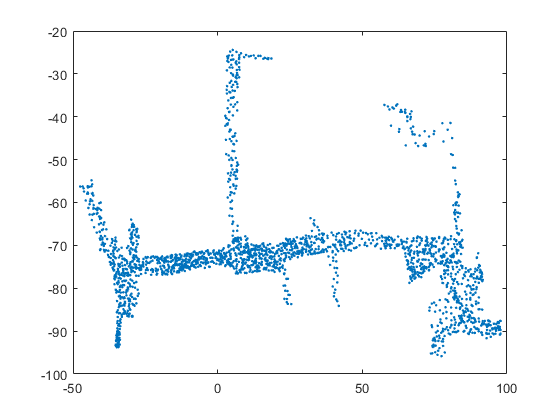

pfn = "large_graph_nodes.txt";
nodes = read(pfn);
nodes(1,:) = [];
plot(nodes(:,2),nodes(:,3),".")